Exercise 1c.

Does this match the predicted anwser from a?  hell yeah it does

load('data_exercise1c.mat');
figure;
plot_FT(y_I,fs);
xlabel('Frequency (mHZ)');
ylim([0,2.6*10^6])
title('FFT of Y_I');
hold off;

Exercise 1d.

clf;
figure;
plot(y_I)
xlabel('Samples');
xlim([2.24225*10^6,2.24232*10^6])
ylabel('Time Response');
title('Time Response of Y_II');

Exercise 1e.

deriv = diff(y_I);
deriv(deriv<0) = 0;
deriv = deriv./max(deriv);
plot(deriv)
xlim([2.24225*10^6,2.24232*10^6])

Exercise 1f.

y = lowpass(deriv, 1.5^5, fs);
y = y./max(y);
plot(y);
xlim([0, 2*10^6]);
ylim([.8, 1]);

Exercise 1g.

y = y - mean(y);
y = (y./max(y)).*.1;
y = decimate(y, 4);
sound(y, 300000/4);

Exercise 2b.

% % load('data_exercise2_try2_50gain.mat');
% load('FM_107_9_Ex2.mat')
% load('data_office.mat')
load('45gain.mat')
% figure;
% plot_FT(y_I,fs_2);
% figure;
% plot(y_I_2)
% y_I_2 = y_I_2 - mean(y_I_2);
% y_I_2 = (y_I_2./max(y_I_2)).*.1;
% y_I_2 = decimate(y_I_2, 4);
% sound(y_I_2, 300000/4);

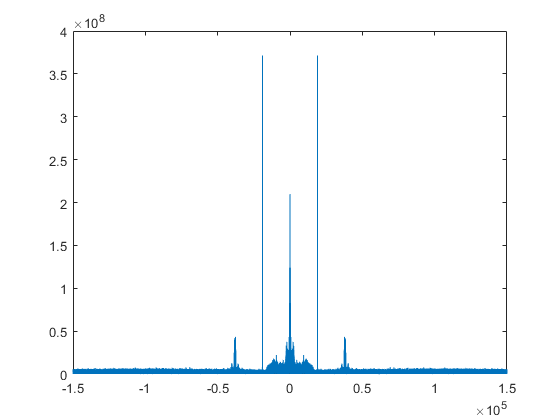

y_Ip = y_I_2;
y_Qp = y_Q_2;
% fs_2 = fs;
% y_Ip = y_I_2 - mean(y_I_2);
% y_Ip = (y_Ip./max(y_Ip)).*.5;
% y_Qp = y_Q_2 - mean(y_Q_2);
% y_Qp = (y_Qp./max(y_Qp)).*.5;
% % y_Ip = decimate(y_Ip, 4);
% % y_Qp = decimate(y_Qp, 4);
a = diff(y_Qp);
m = (a.*y_Ip(1:length(y_Ip)-1)) - (diff(y_Ip).*y_Qp(1:length(y_Qp)-1));
plot_FT(m,fs_2);

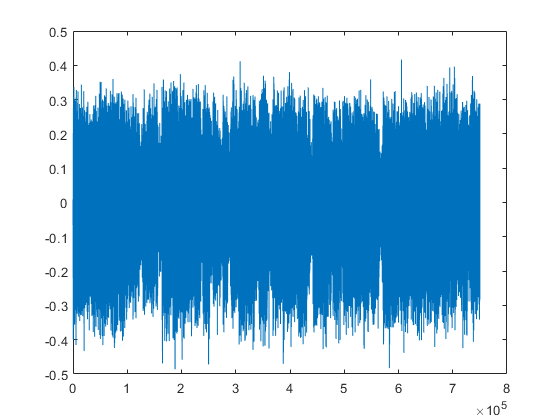

m = lowpass(m, 1.5^5, fs_2);
m = (m/max(abs(m)))*.5;
m = decimate(m,4);
m = m-mean(m);
plot(m);

sound(m,300000/4);